# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu

Max Planck - University of Toronto Centre

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de, nyu.edu}

Version: 240115

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1), the post-op CT scan (hereafter referred to as CT), and **optionally**, the pre-op T2-weighted MRI scan (hereafter referred to as T2). The scans should be in DICOM (.dcm) or NIFTI (.nii) format.

- Make sure that .dcm files in one folder all belong to the same scan (i.e., create dedicated T1/T2/CT folders when preparing DICOM files)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

config.dir_fs = '';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

config.dir_fs_subjects = '';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

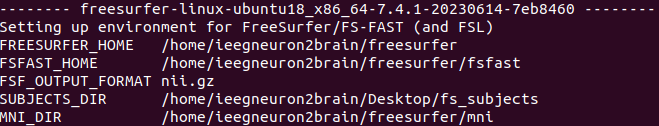

% Type patient ID below
pat.id  = "TWH";
pat.dir = fullfile(config.dir_fs_subjects, pat.id);

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
elec_loc_dir        = strjoin(elec_loc_path_parts(1:end-1), filesep);

cd(elec_loc_dir)
addpath('functions')
addpath('external/spm12')
addpath('external/spm12/toolbox/OldNorm/')
addpath('external/auto_acpc_reorient/')
addpath(genpath('external/dicm2nii'))

% Sanity check if FreeSurfer directory is valid
if isunix
    fs_sanity_check(config)
end

## Import and preprocess scans

Say goodbye to manual preprocessing and coregistration of anatomical scans! The script here imports the T1, CT (and optionally T2) scans into a FreeSurfer subject folder. Moreover, it performs automatic scan centering, AC-PC alignment, coregistration, and defacing. The resulting scans are ready for electrode localization and data sharing.

### Procedure

- Run this section.

- ([UI prompt] If preprocessed files already exist in the output folder, you will be prompted to indicate whether you want to re-import and re-preprocess the scans. The code will simply read and print the paths to preprocessed scans if you choose no.)

- [UI prompt] Indicate whether you want to include T2.

- [UI prompt] Indicate whether you want to import DICOM or NIFTI files.

- [UI file/directory selection] Select T1, CT (and T2) one by one according to prompt in the dialog title. For DICOM, you need to select a folder containing all .dcm files corresponding to one scan. For NIFTI, you need to select a single .nii file.

- Wait for processing. Before the T1 defacing stage, a message window will pop up with instructions on how to proceed.

- During CT processing, a viewer window will pop up to let you inspect the CT scan. You can adjust the minimum value to roughly determine an intensity threshold such that only bones and electrodes are visible. Enter the value into the textbox.

- A viewer window will pop up at the end to allow you to inspect the scans overlaid on top of grayscale T1. The scans should be aligned to each other and defaced. Close the window when done inspecting.

### Output

- The iel subfolder (`pat.dir_iel`) in FreeSurfer subject folder with preprocessed (AC-PC aligned, defaced, and co-registered) scans. Scan file names comply with BIDS format (e.g., sub-XXX_T1w.nii).

- Updated `pat` MATLAB structure.

pat = el_import_scans(pat);

Error using el_import_scans
No file selected

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section creates a new subfolder to store localization outputs (*iel*) and launches iElectrodes.

cd(elec_loc_dir)
iel_info = dir('iElectrodes*');
if isempty(iel_info)
    error(['No iElectrodes package detected. ' ...
        'Please download iElectrods from\n%s\n' ...
        'And move the unzipped folder to %s'], ...
        'https://sourceforge.net/projects/ielectrodes/files/ielectrodes/', ...
        elec_loc_dir)
end
addpath(genpath(iel_info(1).name))

cd(pat.dir_iel)
electrodes_gui

### iElectrodes toolbars

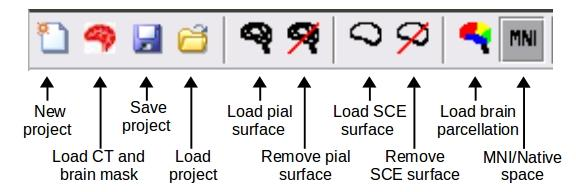

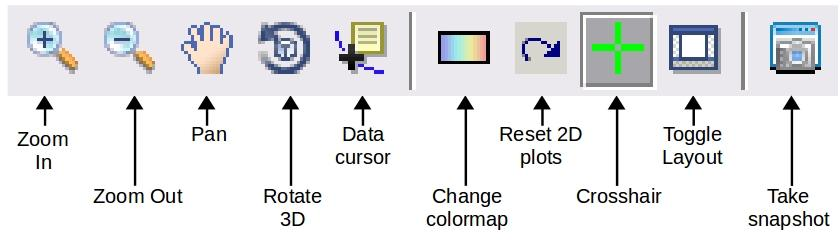

### Steps

- Click "New project" (see icon above) and load **T1w.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan **CT.nii.*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- You can always save your progress at any stage by clicking "Save project" (see icon above). The saved .iel file should contain all the necessary components to retrieve your progress.

- After you are done, click 'Save/Export Electrodes' (see icon below) to save the electrode outputs in various forms. For generating the label tables in later steps, select the second output option to generate a plain txt file with channel name and XYZ coordinates in the native T1 space. It is recommended that you save it as *iel/PATIENT_NAME_elec.txt* (e.g., TWH001_elec.txt)

 

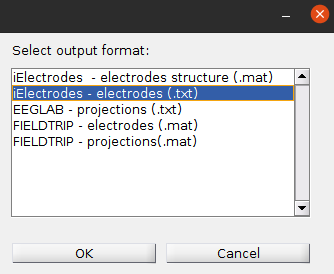

## FreeSurfer recon-all with optional subfield segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

`recon-all` is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

Freesurfer also has a hippocampus/amygdala subfield segmentation feature ([https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala)) with flexible scan input options (use T1 and/or T2).

### Inputs

- [Auto-loaded] Defaced, AC-PC aligned T1 (and T2)

- [Select from dropdown box] hippocampus and amygdala subfield segmentation option. It's recommended to select both T1 + T2 if you have both.

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

subfield_seg_mode = 'T1+T2';
if contains(subfield_seg_mode, 'T2') && ~isfield(pat.t2, 'final')
    error('T2 was requested for subfield segmentation but no T2 was found')
elseif ~exist(pat.t2.final, 'file')
    error('T2 was requested for subfield segmentation but scan not found')
end
el_fs_recon_all(config, pat)
el_fs_hpc_amy_seg(config, pat, subfield_seg_mode)

## Convert .mgz to .nii

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in "mri" subfolder

### Outputs

- .nii files in "mri" subfolder

el_mgz2nii(config, pat)

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Select from GUI] Electrode location .txt file

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- New electrode location .txt file with suffix "_u" in the same folder

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3;

% Select the electrode output .txt file
estimate_micro(pat, micro_to_macro_dist)

## Get FreeSurfer labels in the native space

Since recon-all also produces brain segmentation and parcellation, we can automatically read the label value for each electrode from <aparc.***.mgz> files and find the corresponding label from *$FREESURFER_HOME/FreeSurferColorLUT.txt*. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation)

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in native space) at *iel/PATIENT_NAME_elec_native.csv*

label_native(config, pat)

## Get electrode coordinates in MNI305 and MNI152 space [PENDING FREESURFER COMMUNITY REVIEW]

For group-level visualization of electrode location, mapping locations from native to standardized spaces is usually helpful. This section does two linear transforms to electrode locations to map them to:

- MNI305, also known as the fsaverage space. FreeSurfer automatically co-registers the native T1 onto this space and stores the native-to-MNI305 transformation matrix at *mri/transforms/talairach.xfm.*

- MNI152 space. The MNI305-to-MNI152 matrix is provided in [https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems](https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems).

In addition to generating location tables just like in the previous section, the code also automatically generates .node files. These are useful for visualizing electrode locations in some other softwares (e.g., BrainNet Viewer, Surf Ice). Below is an example visualization of *_elec_mni152.node in BrainNet Viewer:

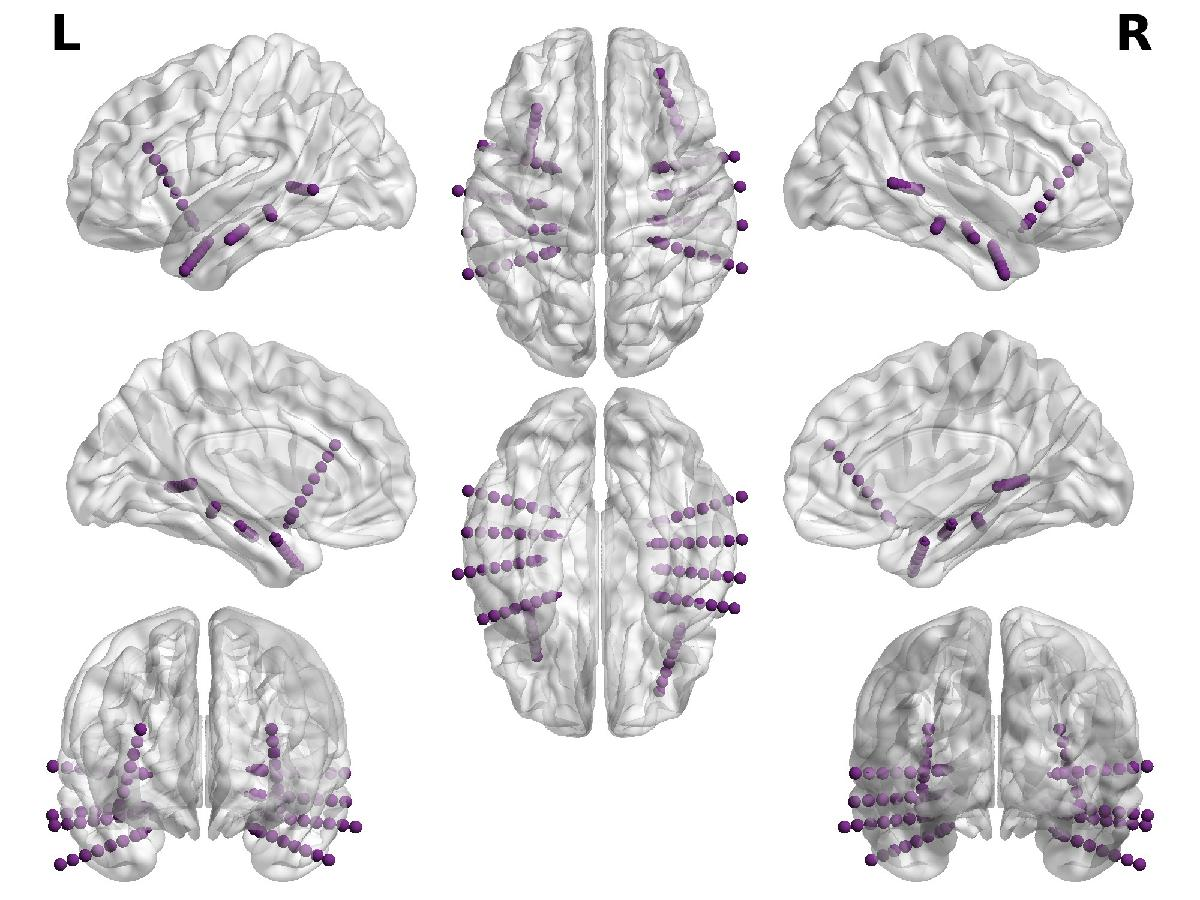

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.csv*

- Electrode location node file (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.node*

- Electrode location table (in MNI152) at *iel/PATIENT_NAME_elec_mni152.csv*

- Electrode location node file (in MNI152) at *iel/PATIENT_NAME_elec_mni152.node*

label_mni(pat)